# Universidade Federal de Campina Grande

# Programa de Pós-Graduação em Engenharia Elétrica

# Estimação e Identificação de Sistemas - 21.2

## Professores: Antonio Marcus Nogueira Lima, Dr.

##                        **Saulo** Oliveira **Dornellas** Luiz, Dr.

## Aluno: Arthur Dimitri Brito Oliveira

O objetivo deste relatório é a descrição do método de identificação de sistemas por subespaço. Discorre-se também sobre diferentes cenários para aplicação deste método, incluindo variados sinais de entrada e ordens do sistema. 

## Relatório de Atividade 11

## Introdução

Nos métodos de identificação por subespaço existe uma ênfase ao estado de um sistema dinâmico, enquanto que, em abordagens clássicas, baseia-se em um arcabouço do tipo entrada-saída. Uma das principais conquistas do método de identificação por subespaços é a demonstração de como os estados do filtro de Kalman podem ser obtidos a partir de dados de entrada e saída utilizando álgebra linear. 

Quando analisado sob a ótica de um problema de ajuste de dados, é evidente que os algoritmos de identificação por subespaço requerem uma parametrização a ser especificada. Diferentemente de outros métodos, aqui utiliza-se os modelos de espaço de estado completos e o único parâmetro é a ordem do sistema. Os métodos clássicos de parametrização trazem alguns problemas:

- É possível que haja problemas de mal-condicionamento das matrizes, como no método de mínimos quadrados. Isso implica em resultados extremamente sensíveis a perturbações. 

- Existe uma sobreposição das parametrizações, visto que nenhuma parametrização cobre todos os possíveis sistemas. 

O método, então, não sofre com esses problemas. É necessário, tão somente, especificar a ordem do modelo, que pode ser determinada por meio da inspeção de alguns valores singulares. 

Algoritmos de identificação por subespaços computam espaços de estados a partir dos dados de entrada e de saída. Sendo assim, dadas $s$ medições da entrada $u_k \in \mathbb{R}^m$ e da saída $y_k \in \mathbb{R}^t$ gerados por um sistema determinístico de ordem $n$:

        $x_{k+1}^d = Ax_k^d + Bu_k$        (1)

          $y_k = Cx_k^d + Du_k$        (2)

Busca-se determinar a ordem $n$ do sistema desconhecido e as matrizes $A,\:\:B,\:\:C\:\:e\:\:D$.

## Não Unicidade da Solução

Diante dos dados de entrada e saída coletados, há inúmeros valores possíveis para os parâmetros capazes de determinar a saída a partir dos dados de entrada $u.$ Supondo que conhece-se as matrizes $A,\:\:B,\:\:C\:\:e\:\:D$ que descrevem as dinâmicas do sistema.

$\left[\matrix{x^{(2)} & x^{(3) & ...& x^{(p+1)}\cr y^{(1)} & y^{(2)} & ... &y^{(p)}}\right ]$= $\left[\matrix{A & B\cr C & D}\right]$$\left[\matrix{x^{(1)} & x^{(2) & ...& x^{(p)}\cr u^{(1)} & u^{(2)} & ... &u^{(p)}}\right ]$

Ao multiplicar ambos os lados por uma matriz arbitraria inversível $T$, tem-se:

$\left[ \matrix{T & 0 \cr 0  & I}\right]$$\left[\matrix{x^{(2)} & x^{(3) & ...& x^{(p+1)}\cr y^{(1)} & y^{(2)} & ... &y^{(p)}}\right ]$= $\left[ \matrix{T & 0 \cr 0  & I}\right]$$\left[\matrix{A & B\cr C & D}\right]$$\left[\matrix{x^{(1)} & x^{(2) & ...& x^{(p)}\cr u^{(1)} & u^{(2)} & ... &u^{(p)}}\right ]$

        $\left[\matrix{Tx^{(2)} & Tx^{(3) & ...& Tx^{(p+1)}\cr y^{(1)} & y^{(2)} & ... &y^{(p)}}\right ]$= $\left[\matrix{TAT^{-1} & TB\cr CT^{-1} & D}\right]$$\left[\matrix{Tx^{(1)} & Tx^{(2) & ...& Tx^{(p)}\cr u^{(1)} & u^{(2)} & ... &u^{(p)}}\right ]$        (3)

Nota-se que os mesmos dados de entrada e saída $(u,y)$ podem ser gerados com o sistema equivalente, onde os parâmetros são multiplicados por uma matriz $T$ inversível. Utiliza-se a matriz $T$ para provocar uma transformação ao vetor de estados. 

## Estratégias para Resolução do Problema

As matrizes $U$ e $Y$ aqui são representadas como um simples histórico dos dados de entrada e saída. Empilha-se as variáveis e aplica-se um deslocamento para a direita. 

        $Y_{1|i} =  \left[\matrix{ y(1)&y(2)&...&y(j) \cr y(2)&y(3)&...&y(j+1) \cr \vdots&\vdots&\ddots&\vdots \cr y(i)&y(i+1)&...&y(i+j+1)}\right]$         (4)

        $U_{1|i} =  \left[\matrix{ u(1)&u(2)&...&u(j) \cr u(2)&y(3)&...&u(j+1) \cr \vdots&\vdots&\ddots&\vdots \cr u(i)&u(i+1)&...&u(i+j+1)}\right]$        (5)

Estas matrizes são denominadas de matrizes de Hankel. Sabendo que $Y$ é gerado a partir de $X$ e de $U$, projeta-se Y no espaço perpendicular àquele gerado por U. Ao fazer isso, a contribuição de U é descartada, já que $HU/U^\perp=0$.  Expressando a saída como uma função linear do vetor linha de $X$ e do vetor linha de $U$. Assim:

$\left[\matrix{ y(1)&y(2)&...&y(j) \cr y(2)&y(3)&...&y(j+1) \cr \vdots&\vdots&\ddots&\vdots \cr y(i)&y(i+1)&...&y(i+j+1)}\right]$=$\left[\matrix{C \cr CA \cr \vdots \cr CA^{-1}}\right]$$\left[\matrix{x_0 & x_1 &x_2& ... &x_{j-1}}\right]$ + $\left[\matrix{D & 0 & 0 & ... & 0 \cr CB & D & 0 & ...&0 \cr \vdots & \vdots & \vdots & \vdots & \vdots \cr CA^{i-2}B & CA^{1-3}B & CA^{i-4}B &... &D}\right]$$\left[\matrix{u_0 & u_1 & u_2 & ...& u_{j-1} 
              \cr u_1 &u_2 &u_3 & ....& u_j 
              \cr \vdots & \vdots & \vdots & \vdots &\vdots 
              \cr u_{i-1} & u_{i} & u_{i+1} & ... & u_{i+j-1}
}\right]$

        $Y_{1|i}=\Gamma_iX_1 + H_iU_{1|i}$        (6)

       $X_{i+1}=A^iX_1+\Delta_iU_{1|i}$       (7)

Para $\Delta_i=\left[\matrix{A^{i-1} & A^{i-2}B & ...&B }\right]$ sendo a matriz de observabilidade reversa. A matriz $\Gamma_i$ é a matriz de observabilidade. Aqui conhece-se, somente, as matrizes $Y$ e $U$. Agora o objetivo é encontrar um subespaço perpendicular ao subespaço definido por $U$  , de modo que a influência de $U$ em $Y$ é removida. A partir da Eq. 6 tem-se:

$X_1 = \Gamma_i^* Y_{1|i}-\Gamma_i^* H_iU_{1|i} $        (8) 

A partir do resultado obtido na Eq. 8, a Eq. 7 torna-se:


$$X_{i+1} = A^i\Gamma_i^*Y_{1|i}- A^i\Gamma_i^*H_iU_{1|i}+\Delta_iU_{1|i} $$


Definindo $L_i=[\Delta_i-A^i\Gamma_i^*H_i \:\:A^i\Gamma_i^*]$ e a matriz de dados$W_{q|i} = \left[ \matrix{U_{1|i} \cr Y_{1|i}}\right]$ pode-se reescrever a Eq.8 e a matriz de dados no instante $i+1$:

        $X_1 =L_iW_{1|i}$        (10)

        $Y_{i+1|2i}=\Gamma_iL_iW_{1|i}+H_iU_{i+1|2i}$        (11)

Fazendo a projeção de $Y_{i+1|2i}$ em $U_{i+1|2i}$:


$$Y_{i+1|2i}/U_{i+1|2i}^\perp = \Gamma_iL_iW_{1|i}/U_{i+1|2i}^\perp+H_iU_{i+1|2i}/U_{i+1|2i}^\perp $$
      

$Y_{i+1|2i}/U_{i+1|2i}^\perp = \Gamma_iL_iW_{1|i}/U_{i+1|2i}^\perp$  (12)

Ao isolar $\Gamma_iL_i$ na Eq. 12, tem-se:

        $\Gamma_iL_i = [Y_{i+1|2i}/U_{i+1|2i}^\perp][W_{1|i}/U_{i+1|2i}^\perp]^*$        (13)

Quando multiplica-se ambos os lados da Eq. 13, obtém-se:

        $\Gamma_iL_iW_{1|i} = [Y_{i+1|2i}/U_{i+1|2i}^\perp][W_{1|i}/U_{i+1|2i}^\perp]^*W_{1|i}$         (14)

Nota-se que os termos $i+1|2i$ referem-se às variáveis a serem identificadas, enquanto que os termos à esquerda dizem respeito às variáveis coletadas. Denominando $[Y_{i+1|2i}/U_{i+1|2i}^\perp][W_{1|i}/U_{i+1|2i}^\perp]^*W_{1|i}=O_{i+1}$, tem-se:

$O_{i+1} = \Gamma_iX_{i+1}$        (15)


$$O_{i+1} = \left[\matrix{ C\cr CA\cr...\cr.CA^{i-1} } \right]\left[\matrix{ x^{(i+1)}&x^{(i+2)}&...&x^{(i+j)}} \right]$$


Fica claro que a matriz $O$ é composta por vetores linha linearmente dependentes. Assim, o posto de $O$ é igual ao posto de $X$. Retomando o resultado obtido na Eq. 15, os valores do lado direito da equação são obtidos por meio do SVD de $O$. O resultado dessa decomposição é interpretado e relacionado com a matriz $X$:


$$O_{i+1} = \Gamma_iX_{i+1}=PSV=PS^{1/2}TT^{-1}S^{1/2}V$$



$$X_{i+1} = T^{-1}S^{1/2}V$$



$$\hat X_{i+1}=S^{1/2}V$$


                $\hat X_{i+1}=TX_{i+1}$        (16)

Sendo assim, o vetor de estados estimado é proporcional ao estado verdadeiro por meio da matriz constante e desconhecida $T$. Apesar de não se conhecer os valores dos estados escondidos, é possível determinar a dimensão do vetor $X$. 

Definindo $V|$ como sendo a matriz $V$ sem a última coluna $V|=\left[\matrix{v^{(1)} & v^{(2)} & ...&v^{(j-1)}}\right]$ e $|V=\left[\matrix{v^{(2)} & v^{(3)} & ...&v^{(j)}}\right]$, de forma análoga:


$$\hat X_{i+2}|=S^{1/2}|V$$



$$\hat X_{i+1}|=S^{1/2}V|$$


Assim, o espaço de estados se torna:

        $\left[\matrix{\hat{X}_{i+2}|\cr Y_{i+1|2i} } \right]= \left[\matrix{\hat{A}&\hat{B} \cr \hat{C}&\hat{D}} \right]\left[\matrix{\hat{X}_{i+1}|\cr U_{i+1|2i} } \right]$        (17)

Tendo conhecimento de $\hat X_{i+2}|$, $Y_{i+1|2i} $, $\hat{X}_{i+1}|$ e $U_{i+1|2i}$, a estimativa das matrizes $A, \:\: B, \:\: C \:\:e \:\:D$ pode ser obtida por meio de:


$$\left[\matrix{\hat{A}&\hat{B} \cr \hat{C}&\hat{D}} \right]= \left[\matrix{\hat{X}_{i+2}|\cr Y_{i+1|2i} } \right]\left[\matrix{\hat{X}_{i+1}|\cr U_{i+1|2i} } \right]^*=\left[\matrix{ TAT^{-1}&TB \cr CT^{-1}&D } \right] $$


## Desenvolvimento

Os exemplos aqui utilizados para validação do algoritmo envolvem sistemas de primeira, segunda e terceira ordem. As excitações utilizadas foram uma onda quadrada e um ruído gaussiano. 

### Exemplo 1: espaço de estados de primeira ordem - excitação: onda quadrada

Considera-se o seguinte sistema de primeira ordem:


$$x^{(k+1)}=0.75x^{(k)} + 0.3u^{(k)}$$



$$y^{(k)}=0.5x^{(k)}$$



$$x^{(1)}=0$$


Utilizando um sinal periódico na forma de uma onda quadrada, excita-se o sistema e observa-se a saída por 100 amostras. Utilizando o método de identificação descrito anteriormente, obtém-se a seguinte representação em espaço de estados e a saída estimada a partir do sistema identificado, conforme ilustra a Figura 1. 

verbose = 1;
addpath 'XI - Subspace Identification\vanoverschee\SUBFUN';

Wflag = 0

A = 0.7500

B = 0.4841

C = 0.3099

D = 7.3177e-16

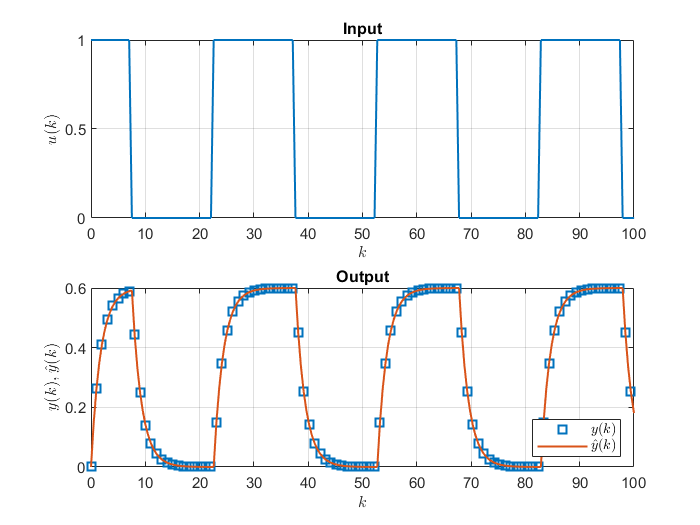

Example_1

**Figura 1: **Sinal de excitação aplicado e saídas: sistema verdadeiro $y(k)$ e sistema aproximado $\hat y(k)$.

Observando o resultado da simulação, verifica-se que os parâmetros $\hat B$ e $\hat C$ não convergem para os valores reais. No entanto, ao comparar as saídas $y(k)$ e $\hat y(k)$, pode-se afirmar que o sistema identificado por subespaços é homólogo ao sistema real. 

### Exemplo 2: espaço de estados de segunda ordem - excitação: onda quadrada

Considera-se o seguinte sistema de segunda ordem:


$$x^{(k+1)} = \left[\matrix{0.9&0&0\cr 0&0.5&0\cr 0&0&0.2} \right]x^{(k)}+\left[\matrix{0.3\cr 0.5\cr 0.8} \right]u^{(k)}$$



$$y^{(k)}=\left[\matrix{1&1&1} \right]x^{(k)}$$


Excita-se o sistema com o mesmo sinal do Exemplo 1. As matrizes do sistema podem ser observadas abaixo, bem como a saída do sistema para os parâmetros estimados, ilustrada na Figura 2.

Wflag = 0

A =     0.8604   -0.1404    0.0114
   -0.1401    0.3794    0.1510
    0.0109    0.1537    0.3601


B =     1.0385
    2.0443
   -0.4725


C =     0.7863    0.3776   -0.0242


D = 5.5110e-16

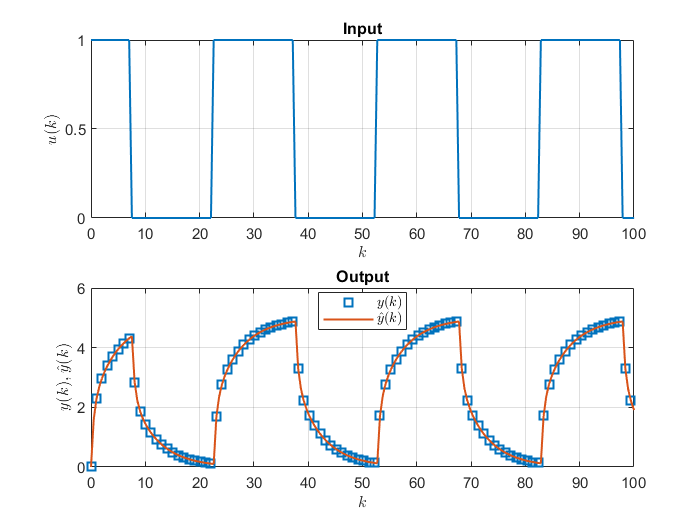

Example_2

**Figura 2: **Sinal de excitação aplicado e saídas: sistemas de segunda ordem verdadeiro $y(k)$ e aproximado $\hat y(k)$.

Observando o resultado da simulação, verifica-se que os parâmetros do espaço de estados não convergem para os valores reais. No entanto, ao comparar as saídas $y(k)$ e $\hat y(k)$, pode-se afirmar que o sistema identificado por subespaços é homólogo ao sistema real. $T\neq1$

### Exemplo 3: espaço de estados de primeira ordem - excitação: ruído branco

O sinal de excitação $u(t)$ agora é um ruído branco para o seguinte espaço de estados:


$$x(k+1) = 0.85x(k)+0.3u(k)$$



$$y(k)=-0.5x(k)$$


Excitou-se o sistema e aplicou-se o método de identificação por subespaços. Os resultados numéricos podem ser observados abaixo e a saída estimada pode ser observada na Figura 3. 

Wflag = 0

A = 0.8500

B = 0.3383

C = -0.4434

D = 3.7496e-17

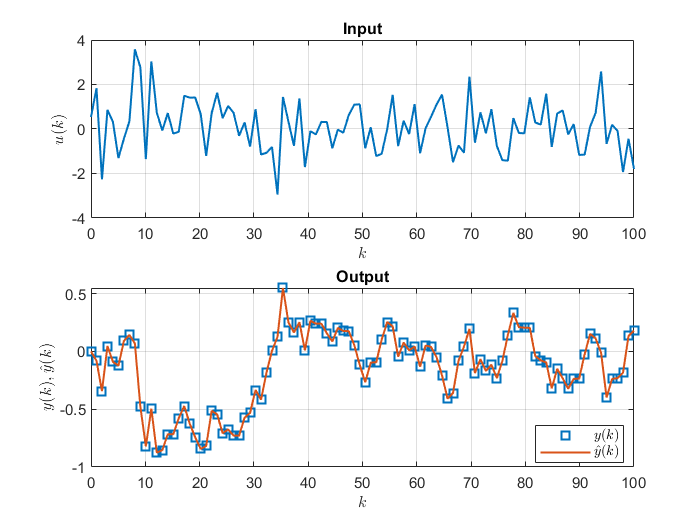

Example_3

**Figura 3: **Ruído branco aplicado ao sistema e as saídas verdadeira$y(k)$ e aproximada $\hat y(k)$.

Observando o resultado da simulação, verifica-se que os parâmetros do espaço de estados convergem para os valores verdadeiros. O sistema identificado equivale, portanto, ao sistema real e $T\approx1$. 

### Exemplo 4: espaço de estados de segunda ordem - excitação: ruído branco

Aplica-se, também, um ruído branco como excitação de um sistema, que agora é de segunda ordem:


$$x(k+1) = \left[\matrix{0.9&0\cr 0&0.5} \right]x(k)+\left[\matrix{0.1\cr 0.3} \right]u(k)$$



$$y(k)=\left[\matrix{1&1} \right]x(k)$$


Aplicando o método descrito anteriormente, obtém-se as saídas observadas na Figura 4. 

Wflag = 0

A =     0.7595    0.1990
    0.1832    0.6405


B =     0.5277
   -0.2615


C =     0.6397   -0.2388


D = 5.2757e-17

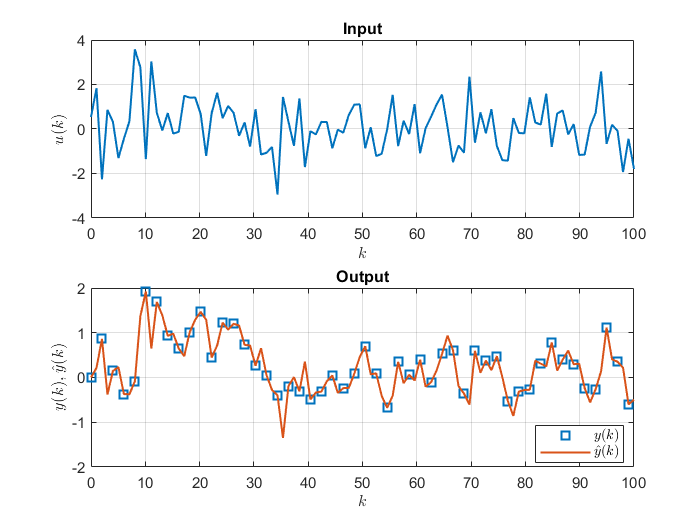

Example_4

**Figura 4: **Ruído branco aplicado ao sistema e as saídas verdadeira$y(k)$ e aproximada $\hat y(k)$.

Observando o resultado da simulação, verifica-se que os parâmetros do espaço de estados não convergem para os valores verdadeiros. Quando se compara as saídas $y(k)$ e $\hat y(k)$, observa-se uma similaridade nas dinâmicas, embora o espaço de estados aproximado não reflita com fidelidade as flutuações da dinâmica esperada. 

## Referências

[1]  VAN OVERSCHEE, DE MOR.** Subspace Identification for Linear Systems. Theory, implementation, applications.  **Kluwer Academic Publishers, 1996.